Aby to fungovalo, musí se přidat cesta, zároveň zavedeme nápovědu (stačí spustit na začátku relace jednou)

addpath(genpath('/mnt/nfs/osmera/Documents/MATLAB/MNPBEM17'));

run('/mnt/nfs/osmera/Documents/MATLAB/MNPBEM17/makemnpbemhelp.m')

Successfully created search database.


# **Úloha1: Ag disk**

Budeme modelovat Ag nano disk o různých průměrech a sledovat **EELS **spektra. 

## **Inicializace: nastavení pro simulaci**

Nastavení pro řešení pomocí **B**oundary **E**lement **M**ethod numerické smiulace. Využije se `bemoptions`, kde 

- `'sim'` vybírá mezi `'stat'` a `'ret'`, tj. kvazistatickým a retardovaným modelem.

- `'interp'` je nastavení interpolace meshe, vybírá se mezi `'flat'` a `'curv'`

%% initialization
%  options for BEM simulation
op1 = bemoptions( 'sim', 'ret',  'interp', 'curv' );
op2 = bemoptions( 'sim', 'stat', 'interp', 'curv' );

Následující proměnná ukládá všechny dielektrické konstanty prostředí: `epstab = { ``vzduch``, ``stříbro`` }; `

`epstable()` vrací dielektrickou funkci z tabelovaných hodnot.

%  table of dielectric function
epstab = { epsconst( 1 ), epstable( 'silver.dat' ) };

### Geometrie

#### Disk

Nyní se nadefinuje geometrie. Průměr a výšku disku:

%  diameter of disk
diameter =30;
height = 5;

Tvar disku -- fce `polygon( ``#vertices, ``  ) ??????`

`edge` nějak vyrobí hranu

%  polygon for disk
poly = polygon( 25, 'size', [ 1, 1 ] * diameter );
%  edge profile for disk
edge = edgeprofile( height, 11 );
%  extrude polygon to nanoparticle
p = comparticle( epstab, { tripolygon( poly, edge ) }, [ 2, 1 ], 1, op1 );

#### Elektronový svazek:

%  width of electron beam and electron velocity
[ width, vel ] = deal( 0.5, eelsbase.ene2vel( 200e3 ) );

Vzdálenost svazku od středu disku: ???

%  impact parameters (0, R/2, R)
imp = [ 0, 0; 0.48, 0; 0.96, 0 ] * diameter / 2;

Testované energie:

%  loss energies in eV
ene = linspace( 2.0, 4.0, 100 );

%  convert energies to nm
units;  enei = eV2nm ./ ene;

## Vlastní  BEM simulace

%%  BEM solution
%  BEM solvers
bem1 = bemsolver( p, op1 );
bem2 = bemsolver( p, op2 );
%  electron beam excitation
exc1 = electronbeam( p, imp, width, vel, op1 );
exc2 = electronbeam( p, imp, width, vel, op2 );
%  surface and bulk losses
[ psurf1, pbulk1 ] = deal( zeros( size( imp, 1 ), numel( enei ) ) );
[ psurf2, pbulk2 ] = deal( zeros( size( imp, 1 ), numel( enei ) ) );

multiWaitbar( 'BEM solver', 0, 'Color', 'g', 'CanCancel', 'on' );
%  loop over wavelengths
for ien = 1 : length( enei )
  %  surface charges
  sig1 = bem1 \ exc1( enei( ien ) );
  sig2 = bem2 \ exc2( enei( ien ) );
  %  EELS losses
  [ psurf1( :, ien ), pbulk1( :, ien ) ] = exc1.loss( sig1 );
  [ psurf2( :, ien ), pbulk2( :, ien ) ] = exc2.loss( sig2 );
  
  multiWaitbar( 'BEM solver', ien / numel( enei ) );
end
%  close waitbar
multiWaitbar( 'CloseAll' );

#### Vynesení do grafu

%final plot
clf
plot( ene, psurf1 + pbulk1 );  hold on
if ~verLessThan( 'matlab', '8.4.0' ), set( gca, 'ColorOrderIndex', 1 );  end
plot( ene, psurf2 + pbulk2, '--' ); 

xlabel( 'Loss energy (eV)' );
ylabel( 'Loss probability (eV^{-1})' );

legend( '0, ret', 'R/2', 'R', '0, qs' );
title(sprintf('diameter = %i nm, height = %i nm', diameter, height))

## Různé výstupy

Fig.: diameter = 30 a height = 5

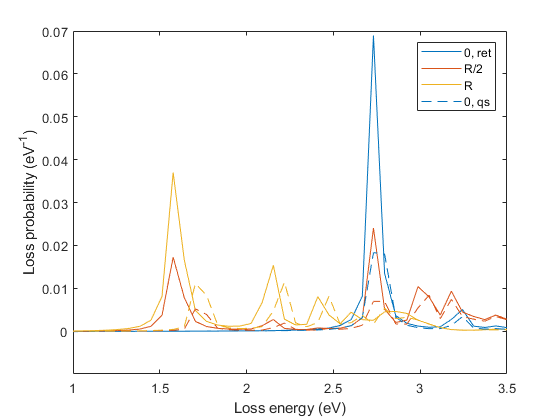

Fig:diameter = 50 a height = 5

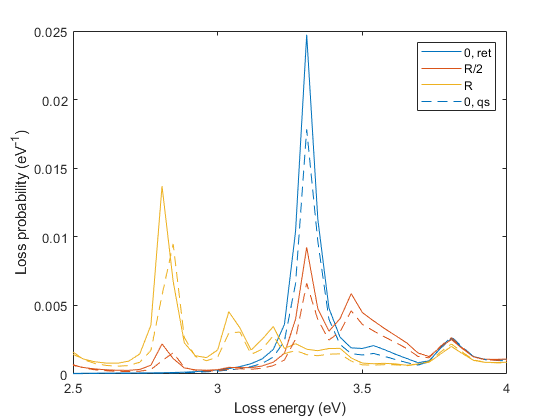

Fig.: diameter = 80 a height = 5:

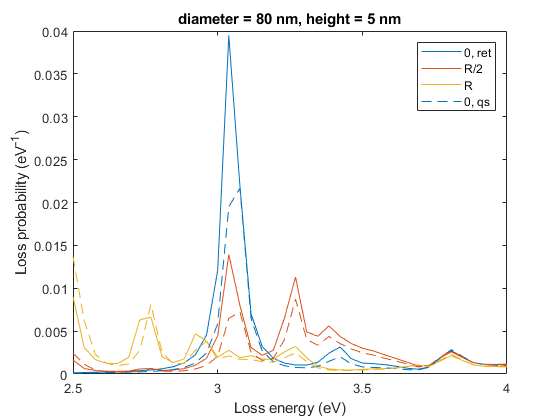

Fig.: diameter = 120 a height = 5

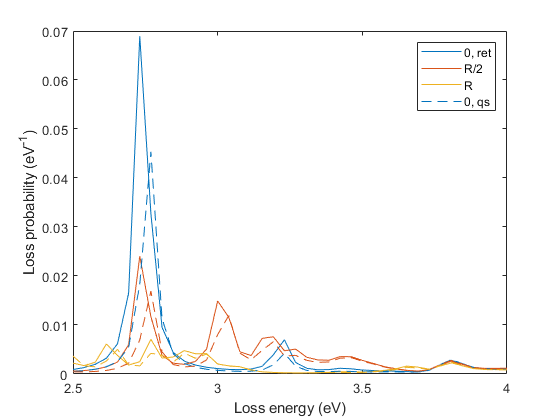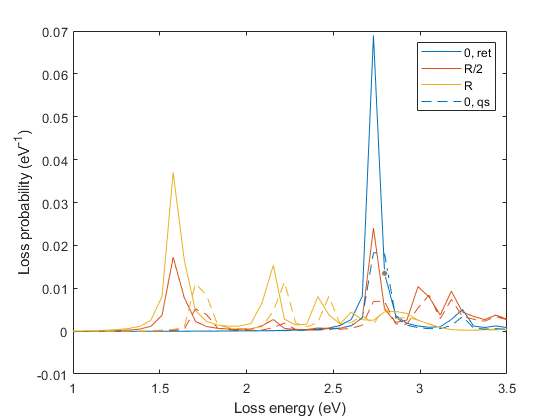

Když se svýší diameter, posouvá se ztrátová pravděpodobnost k nižším energiím, 

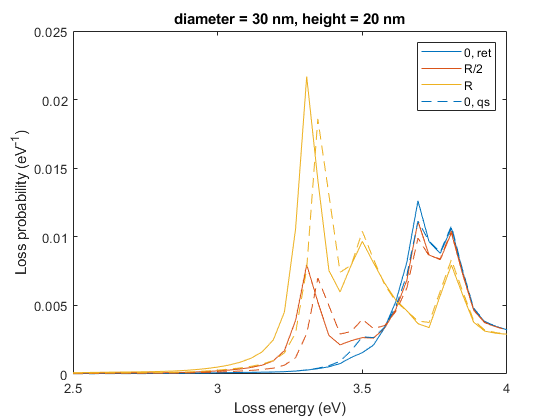

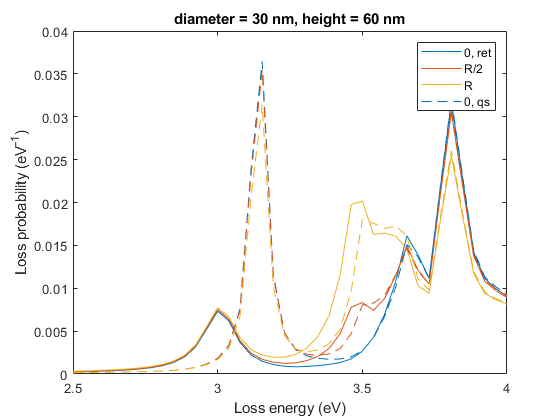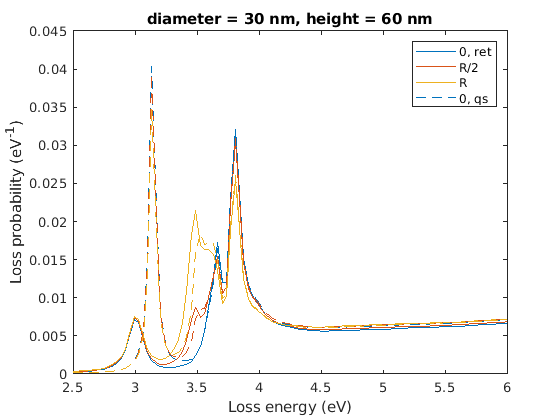

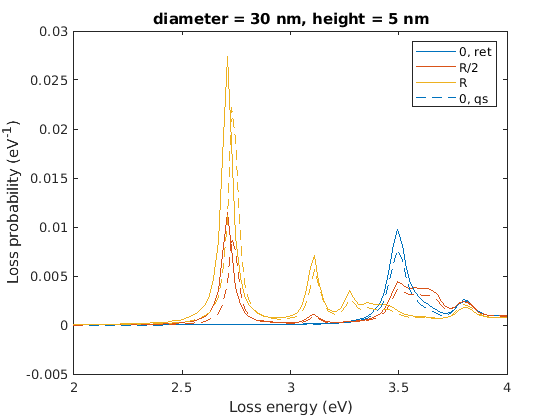

# EEL probability Tvar 30 nm x 5 nm

units;
%  loss energies (extracted from ABOVE)
ene = [ 2.75, 3.11 , 3.5, 3.8];
%  wavelengths
enei = eV2nm ./ ene;

%  mesh for electron beams
[ x, y ] = meshgrid( linspace( -diameter, diameter, 50 ), linspace( 0, diameter, 50 ) );
%  impact parameters
impact = [ x( : ), y( : ) ];
%  width of electron beam and electron velocity 
%[ width, vel ] = deal( 0.2, eelsbase.ene2vel( 200e3 ) );

## BEM simulation

op = op1

op = struct with fields:
          sim: 'ret'
      waitbar: 1
    RelCutoff: 3
        order: 5
       interp: 'curv'


bem = bemsolver( p, op );

%  EELS excitation
exc = electronbeam( p, impact, width, vel, op );
%  electron energy loss probabilities
[ psurf, pbulk ] = deal( zeros( size( impact, 1 ), length( enei ) ) );

multiWaitbar( 'BEM solver', 0, 'Color', 'g', 'CanCancel', 'on' );
%  loop over energies
for ien = 1 : length( enei )
  %  surface charges
  sig = bem \ exc( enei( ien ) );
  %  EELS losses
  [ psurf( :, ien ), pbulk( :, ien ) ] = exc.loss( sig );
  
  multiWaitbar( 'BEM solver', ien / numel( enei ) );
end
%  close waitbar
multiWaitbar( 'CloseAll' );

## final plot

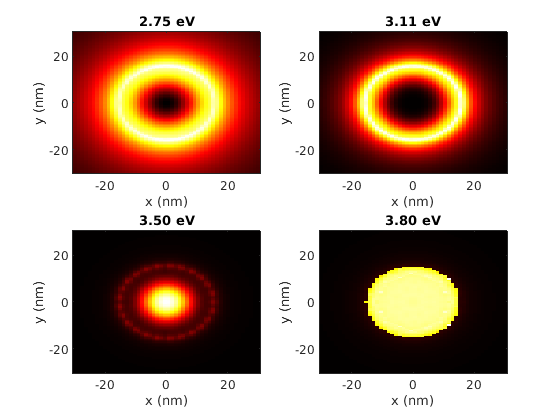

xx = [ min( x( : ) ), max( x( : ) ) ];
yy = [ - max( y( : ) ), max( y( : ) ) ];

%  plot EELS maps
for i = 1 : 4
    
  subplot( 2, 2, i );
  
  %  reshape loss probability
  prob = reshape( psurf( :, i ) + pbulk( :, i ), size( x ) );
 % prob2 = [prob(:,:-1:) , prob(:,:1:)] 
  
  %  add second part of triangle
  imagesc( xx, yy, [ flipud( prob( 2 : end, : ) ); prob ] ); 

  set( gca, 'YDir', 'norm' );
  colormap hot( 255 );

  xlabel( 'x (nm)' );
  ylabel( 'y (nm)' );
  
  %title( subsref( { '2.75 eV', '3.11 eV', '3.75 eV' , '3.8 eV'},  ...
                                          %substruct( '{}', { i } ) ) );
  title(  num2str(ene(i)', '%.2f eV') )                            
end

# Charge density

enef = 3.5;
sig = bem1 \ exc1( eV2nm / enef )

compstruct : 
    sig1: [428×3 double]
    sig2: [428×3 double]
      h1: [428×3×3 double]
      h2: [428×3×3 double]
       p: [1×1 comparticle]
    enei: 354.2404



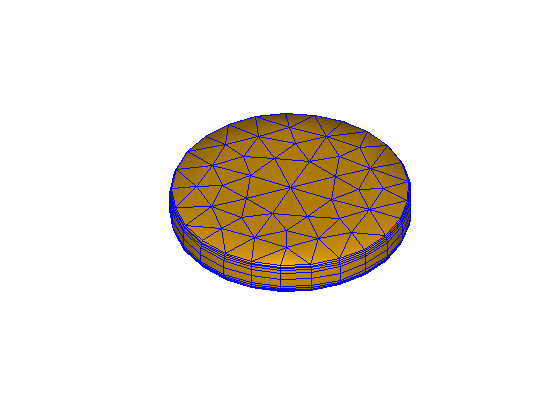

%hledat "charge density"


%  polygons for plate around nanoparticle
%poly1 = shiftbnd( set( poly, 'z', 0 ), 1 );
%poly2 = polygon3( polygon( 4, 'size', [ 50, 50 ] ), 0 );
%  make plate around triangle
%p2 = plate( [ poly1, poly2 ] );



clf
%  plot particle and decay rate on plate
plot( p, 'EdgeColor', 'b' );
%plot( p, sig.sig2 );                    %this command for unk reasons work only if typed in console

colormap hot( 255 );

## Using Eigensolver

opeig = bemoptions('sim','stat','nev', 20);     % 'nev
% 
%  ' stands for number ( in our case 20) eigenvalues
bemeig = bemstateig(p, opeig);

eigencharges = bemeig.ur;       % This line initiates eigensolver

for nEigenmode = 2:4    %desired mode index 
                  
    sig = compstruct(p,enei);         %compstruct object that can be fed to the "potential" function
    sig.sig = bemeig.ur(:,nEigenmode);    %replacement of an ordinary charge by the pseudocharge
    %% extracting potential in 3D
    x = linspace( - diameter, diameter, 101 );
    y = linspace( - diameter, diameter, 101 );
    z = linspace( - diameter, diameter, 101 );
    [X, Y, Z] = ndgrid( x, y, z );
    
    pt = compoint( p, [ X(:), Y(:), Z(:) ], 'medium', 1, 'mindist', 1e-1 );      
    g = greenfunction( pt, p, opeig );
    pot = potential( g, sig );
    
    phiOut = zeros(size(X));
    tmp = struct(pt);
    SubIndex = tmp.ind{1};
    phiOut(SubIndex) = pot.phi1;
    
    pt = compoint( p, [ X(:), Y(:), Z(:) ], 'medium', 2, 'mindist', 1e-1 );      
    g = greenfunction( pt, p, op );
    pot = potential( g, sig );
    
    phiIn = zeros(size(X));
    tmp = struct(pt);
    SubIndex = tmp.ind{2};
    phiIn(SubIndex) = pot.phi1;
    
    phiInOut = phiIn + phiOut;
    
    B=reshape(phiInOut,101,101*101);
    fname = sprintf('Documents/MATLAB/MNPBEM17/MY_PROJECTS/OUTPUT/potential_disk_eig%d.dat', nEigenmode);
    %open(fname, 'w')
    save(fname,'B','-ascii')
    
    figure(nEigenmode)
    plot(p, sig.sig)
    title(sprintf('Eigenmode %d', nEigenmode))
end

Out of memory.

Error in eval1 (line 82)
      Gp = - cat( 3, x ./ d .^ 3 * area, y ./ d .^ 3 * area, z ./ d .^ 3 * area );

Error in greenstat/eval (line 20)
  [ varargout{ 1 : nargout } ] = eval1( obj, varargin{ : } );

Error in 